clear;
close all;
clc;

%% Robot parameters
param = robot_parameters();

%% Initial state
q0 = [
    deg2rad(120);
    deg2rad(60)
];

dq0 = [
    0;
    0
];

x0 = [
    q0;
    dq0
];

%% Simulation settings
tspan = [0, 3.0];

options = odeset( ...
    'RelTol', 1e-8, ...
    'AbsTol', 1e-10, ...
    'MaxStep', 1e-3);

%% Run simulation
[t, x] = ode45( ...
    @(t, x) forward_dynamics_MCG(t, x, param), ...
    tspan, ...
    x0, ...
    options);

%% Extract states
q  = x(:, 1:2);
dq = x(:, 3:4);

number_of_samples = length(t);

%% Allocate log arrays
ddq = zeros(number_of_samples, 2);

c_log = zeros(number_of_samples, 2);
G_log = zeros(number_of_samples, 2);

kinetic_energy   = zeros(number_of_samples, 1);
potential_energy = zeros(number_of_samples, 1);
total_energy     = zeros(number_of_samples, 1);

%% Recalculate dynamics at each output time
for k = 1:number_of_samples

    q_k  = q(k, :).';
    dq_k = dq(k, :).';

    %% Dynamics
    M_k = mass_matrix(q_k, param);
    c_k = coriolis_torque(q_k, dq_k, param);
    G_k = gravity_torque(q_k, param);

    %% No applied torque
    tau_k = [
        0;
        0
    ];

    %% Joint acceleration
    ddq_k = M_k \ (tau_k - c_k - G_k);

    %% Kinetic energy
    kinetic_energy(k) = ...
        0.5 * dq_k.' * M_k * dq_k;

    %% Potential energy
    q1_k = q_k(1);
    q2_k = q_k(2);

    potential_energy(k) = ...
        param.m1 * param.g * param.r1 * sin(q1_k) ...
        + param.m2 * param.g * ...
        (param.l1 * sin(q1_k) ...
        + param.r2 * sin(q2_k));

    %% Total mechanical energy
    total_energy(k) = ...
        kinetic_energy(k) ...
        + potential_energy(k);

    %% Store values
    ddq(k, :) = ddq_k.';
    c_log(k, :) = c_k.';
    G_log(k, :) = G_k.';

end

%% Display final state
disp('Final joint angle [deg]');

Final joint angle [deg]


disp(rad2deg(q(end, :)));

  170.6454 -343.6263




disp('Final joint velocity [rad/s]');

Final joint velocity [rad/s]


disp(dq(end, :));

    3.7695   -7.4368




%% Energy conservation
relative_total_energy_variation = ...
    (max(total_energy) - min(total_energy)) ...
    / max(abs(mean(total_energy)), eps);

disp('Relative total-energy variation');

Relative total-energy variation


disp(relative_total_energy_variation);

   4.9089e-09



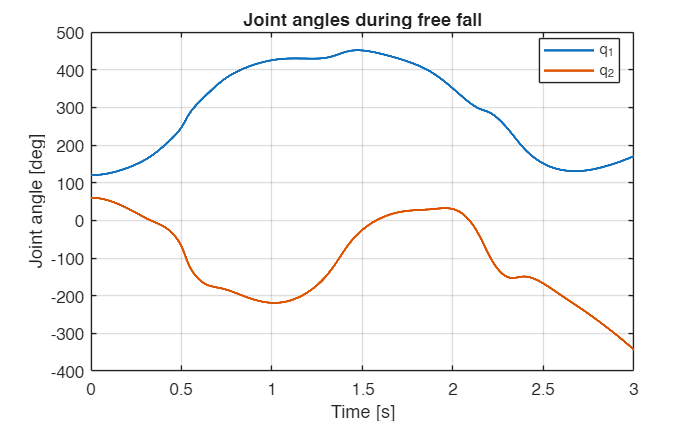


%% Joint angle
figure;

plot(t, rad2deg(q(:, 1)), 'LineWidth', 1.5);
hold on;
plot(t, rad2deg(q(:, 2)), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint angle [deg]');

legend('q_1', 'q_2', ...
    'Location', 'best');

title('Joint angles during free fall');

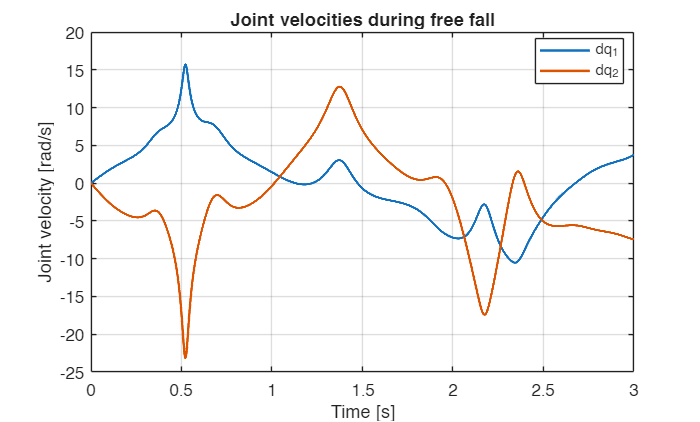


%% Joint velocity
figure;

plot(t, dq(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, dq(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint velocity [rad/s]');

legend('dq_1', 'dq_2', ...
    'Location', 'best');

title('Joint velocities during free fall');

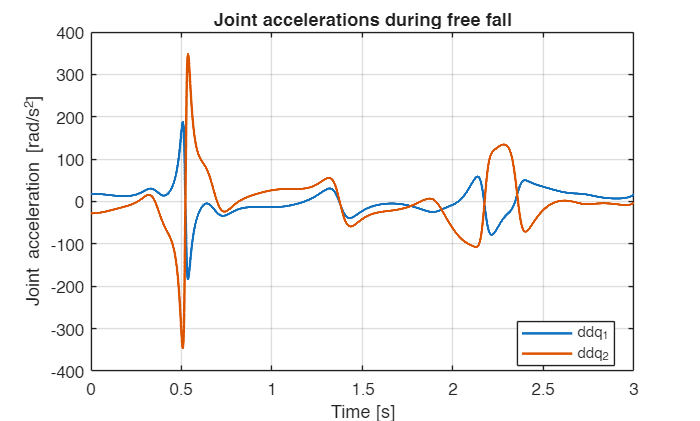


%% Joint acceleration
figure;

plot(t, ddq(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, ddq(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint acceleration [rad/s^2]');

legend('ddq_1', 'ddq_2', ...
    'Location', 'best');

title('Joint accelerations during free fall');

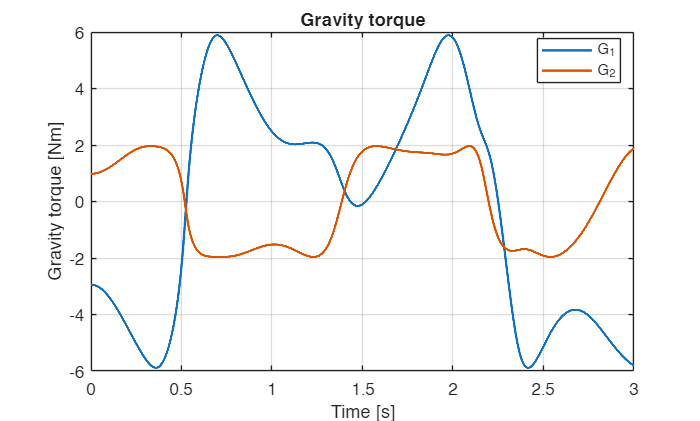


%% Gravity torque
figure;

plot(t, G_log(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, G_log(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Gravity torque [Nm]');

legend('G_1', 'G_2', ...
    'Location', 'best');

title('Gravity torque');

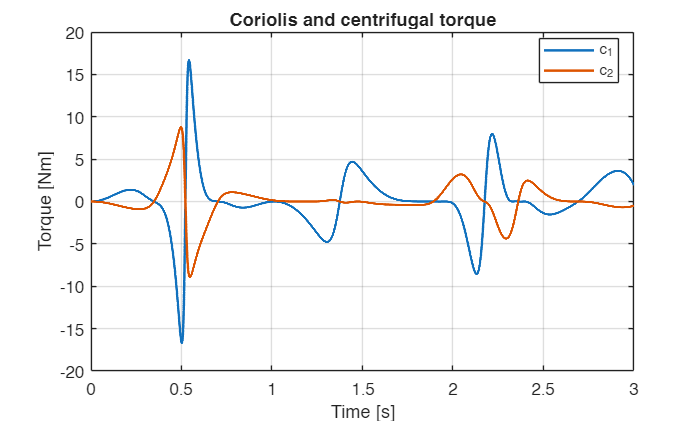


%% Coriolis and centrifugal torque
figure;

plot(t, c_log(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, c_log(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Torque [Nm]');

legend('c_1', 'c_2', ...
    'Location', 'best');

title('Coriolis and centrifugal torque');

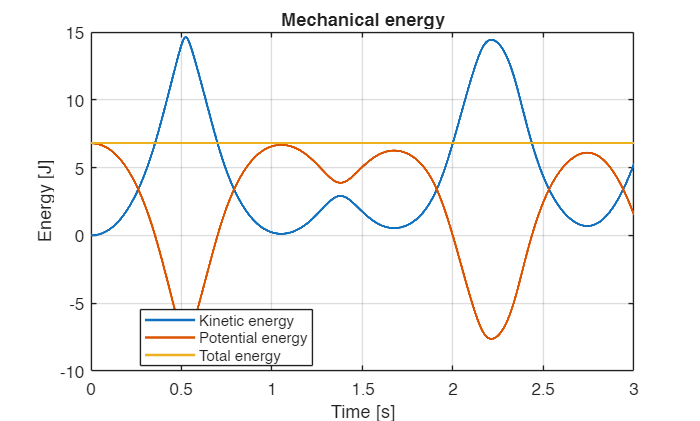


%% Mechanical energy
figure;

plot(t, kinetic_energy, 'LineWidth', 1.5);
hold on;
plot(t, potential_energy, 'LineWidth', 1.5);
plot(t, total_energy, 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Energy [J]');

legend( ...
    'Kinetic energy', ...
    'Potential energy', ...
    'Total energy', ...
    'Location', 'best');

title('Mechanical energy');